Run 1: Success.
Run 2: Success.
Run 3: Success.


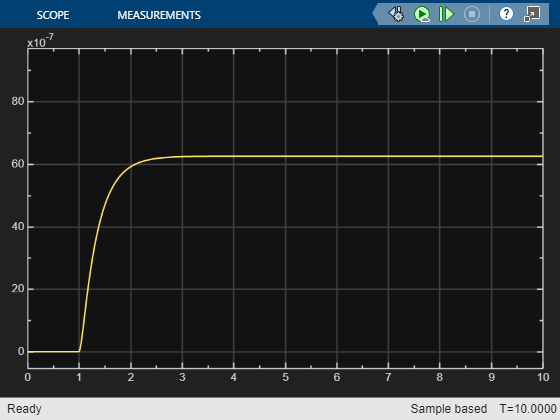

%% COMPLETE FFT OPTIMIZATION (Hybrid Mode)
clc; clear; close all;

%% 1. Define Constants
m = 250;     
k = 16000;   
Fs = 1000;   
Ts = 1/Fs;
T_sim = 10;   

%% 2. Optimization Setup
test_values = [500, 2200, 6000]; 
colors = {'r', 'b', 'g'}; 
legends = {}; 

figure('Name', 'FFT Optimization', 'Color', 'w'); hold on;

%% 3. PREPARE SIMULINK ( The Magic Step )
% Load the model into memory without running it
load_system('car_model');

% DISABLE the Spectrum Analyzer so it doesn't crash the script
% (Note: If your block is named something else, change 'Spectrum Analyzer' below)
try
    set_param('car_model/Spectrum Analyzer', 'Commented', 'on');
catch
    warning('Could not find Spectrum Analyzer block. Ignoring...');
end

%% 4. The Loop
for i = 1:length(test_values)
    
    c = test_values(i); 
    
    % Run Simulink
    out = sim('car_model');
    
    % --- DATA EXTRACTION ---
    all_vars = who(out);
    data_candidates = setdiff(all_vars, {'tout', 'SimulationMetadata', 'ErrorMessage'});
    
    if isempty(data_candidates)
        error('No data found. Check "To Workspace" block.');
    end
    
    actual_name = data_candidates{1};
    raw_data = out.(actual_name);
    
    % Convert Objects to Numbers
    if isa(raw_data, 'timeseries')
        x = raw_data.Data;
    elseif isstruct(raw_data) && isfield(raw_data, 'signals')
        x = raw_data.signals.values;
    else
        x = raw_data;
    end
    
    x = squeeze(x); 
    
    % --- FFT ---
    x_detrend = x - mean(x);    
    L = length(x_detrend);
    Y = fft(x_detrend);
    
    P2 = abs(Y/L);
    P1 = P2(1:floor(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(floor(L/2)))/L;   
    
    % --- PLOT ---
    plot(f, P1, 'Color', colors{i}, 'LineWidth', 2);
    legends{end+1} = ['c = ' num2str(c)];
    fprintf('Run %d: Success.\n', i);
    
end 

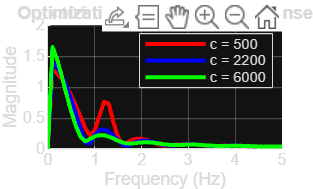


%% 5. CLEAN UP (Wake up the block)
% Re-enable the Spectrum Analyzer so you can use it manually later
try
    set_param('car_model/Spectrum Analyzer', 'Commented', 'off');
catch
end

%% 6. Formatting
grid on;
legend(legends);
title('Optimization: Frequency Response');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 5]);